#### Modulation

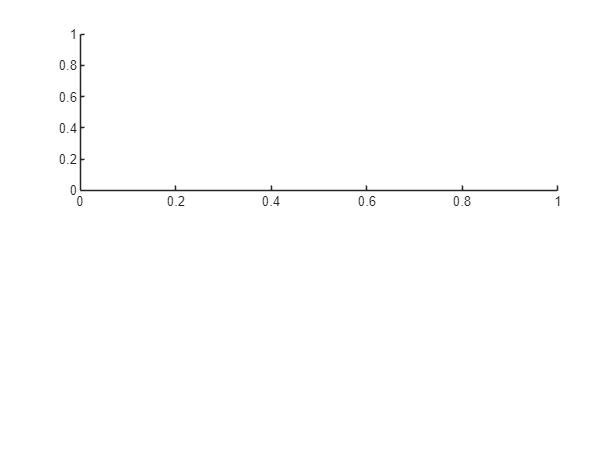

if use_audio
    f1 = 1000; % Trägerfrequenz 1
    f2 = 15000; % Trägerfrequenz 2
else
    f1 = 250; % Trägerfrequenz 1
    f2 = 500; % Trägerfrequenz 2
end

modulated_signal_1 = h1 .* cos(2*pi*f1*t);
modulated_signal_2 = h2 .* cos(2*pi*f2*t);

[FFT_modulated_signal_1, FFT_modulated_signal_2] = FFT(modulated_signal_1, modulated_signal_2);
shifted_FFT_modulated_signal_1_magnitude = abs([FFT_modulated_signal_1(N_half+1:end), FFT_modulated_signal_1(1:N_half)]);
shifted_FFT_modulated_signal_2_magnitude = abs([FFT_modulated_signal_2(N_half+1:end), FFT_modulated_signal_2(1:N_half)]);

figure;
tiledlayout(2,1)
nexttile

plot(f_c_raw, 1/N*shifted_FFT_modulated_signal_1_magnitude);

Unrecognized function or variable 'f_c_raw'.

hold on
plot(f_c_raw, 1/N*shifted_FFT_iterativ_signal_1_magnitude);
%plot(f_c_raw, 1/N*abs(fftshift(fft(h1))));
%plot(f_c_mod, 1/N*abs(fftshift(fft(cos(2*pi*f1*t)))))
hold off
title('Frequenzspektrum des Signals 1');
xlabel('Frequenz (Hz)');
ylabel('Amplitude');
legend('FFT signal 1 modulated','FFT signal 1 original')

nexttile
plot(f_c_raw, 1/N*shifted_FFT_modulated_signal_2_magnitude);
hold on
plot(f_c_raw, 1/N*shifted_FFT_iterativ_signal_2_magnitude);
hold off
title('Frequenzspektrum des Signals 1');
xlabel('Frequenz (Hz)');
ylabel('Amplitude');
legend('FFT signal 2 modulated','FFT signal 2 original')
figure()
tiledlayout(2,1)
nexttile
plot(t,h1)
hold on
plot(t,modulated_signal_1)
hold off
xlim([0 max(t)])
xlim([0.15 0.25]);
title('Signal 1 modulated','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 1 filtered','Signal 1 modulated')

nexttile
plot(t,h2)
hold on
plot(t,modulated_signal_2)
hold off
xlim([0 max(t)])
xlim([0.16 0.17]);
title('Signal 2 modulated','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 2 filtered','Signal 2 modulated')

#### Combination

combined_signal = modulated_signal_1 + modulated_signal_2;

figure()
plot(t,combined_signal)
xlim([0 max(t)])
title('Signals combined','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);

#### Demodulation

demodulated_signal_1 = combined_signal .* 2 .* cos(2*pi*f1*t);
demodulated_signal_2 = combined_signal .* 2 .* cos(2*pi*f2*t);

[FFT_demodulated_signal_1, FFT_demodulated_signal_2] = FFT(demodulated_signal_1, demodulated_signal_2);
shifted_FFT_demodulated_signal_1_magnitude = abs([FFT_demodulated_signal_1(N_half+1:end), FFT_demodulated_signal_1(1:N_half)]);
shifted_FFT_demodulated_signal_2_magnitude = abs([FFT_demodulated_signal_2(N_half+1:end), FFT_demodulated_signal_2(1:N_half)]);

n=100;
b = fir1(n-1, cutoff_f/(fs/2), 'low',w_hamming_FIR1_pre); % Filterkoeffizienten
demodulated_signal_1_filt = conv(demodulated_signal_1, b, 'same'); % Gefilterte Ausgabe
demodulated_signal_2_filt = conv(demodulated_signal_2, b, 'same'); % Gefilterte Ausgabe

[FFT_demodulated_signal_1_filt, FFT_demodulated_signal_2_filt] = FFT(demodulated_signal_1_filt, demodulated_signal_2_filt);
shifted_FFT_demodulated_signal_1_magnitude_filt = abs([FFT_demodulated_signal_1_filt(N_half+1:end), FFT_demodulated_signal_1_filt(1:N_half)]);
shifted_FFT_demodulated_signal_2_magnitude_filt = abs([FFT_demodulated_signal_2_filt(N_half+1:end), FFT_demodulated_signal_2_filt(1:N_half)]);

figure;
tiledlayout(2,1)
nexttile
%plot(f_c_raw, 1/N*shifted_FFT_demodulated_signal_1_magnitude);
hold on
plot(f_c_raw, 1/N*shifted_FFT_demodulated_signal_1_magnitude_filt);
plot(f_c_raw, 1/N*shifted_FFT_iterativ_signal_1_magnitude);
%plot(f_c_raw, 1/N*abs(fftshift(fft(h1))));
%plot(f_c_mod, 1/N*abs(fftshift(fft(cos(2*pi*f1*t)))))
hold off
title('Frequenzspektrum des Signals 1');
xlabel('Frequenz (Hz)');
ylabel('Amplitude');
legend('FFT signal 1 demodulated','FFT signal 1 demodulated filtered','FFT signal 1 original')
xlim([-cutoff_f-2000 cutoff_f+2000])

nexttile
%plot(f_c_raw, 1/N*shifted_FFT_demodulated_signal_2_magnitude);
hold on
plot(f_c_raw, 1/N*shifted_FFT_demodulated_signal_2_magnitude_filt);
plot(f_c_raw, 1/N*shifted_FFT_iterativ_signal_1_magnitude);
hold off
title('Frequenzspektrum des Signals 1');
xlabel('Frequenz (Hz)');
ylabel('Amplitude');
legend('FFT signal 2 demodulated','FFT signal 2 demodulated filtered','FFT signal 2 original')
xlim([-cutoff_f-2000 cutoff_f+2000])


figure()
tiledlayout(2,1)
nexttile
plot(t,demodulated_signal_1)
hold on
plot(t,demodulated_signal_1_filt)
plot(t,h1)
hold off
xlim([0.25 0.3]);%xlim([0 max(t)])
title('Signal 1 demodulated','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 1 demodulated','Signal 1 demodulated filtered','Signal 1 original');

nexttile
plot(t,demodulated_signal_2)
hold on
plot(t,demodulated_signal_2_filt)
plot(t,h2)
hold off
xlim([0.2 0.3]);%xlim([0 max(t)])
title('Signal 2 demodulated','Interpreter','Latex')
xlabel('$t$(s)','Interpreter','Latex', 'FontSize', 13)
ylabel('$s[t]$', 'Interpreter', 'latex', 'FontSize', 13);
legend('Signal 2 demodulated','Signal 2 demodulated filtered','Signal 2 original');

 
volume = 1; % Lautstärke zwischen 0 und 1
signal_1_reduced = h1 * volume;
sound(signal_1_reduced, fs)

 
volume = 0.5; % Lautstärke zwischen 0 und 1
signal_1_reduced = h2 * volume;
sound(signal_1_reduced, fs)

 
volume = 1; % Lautstärke zwischen 0 und 1
signal_1_reduced = demodulated_signal_1_filt * volume;
sound(signal_1_reduced, fs)

 
volume = 0.5; % Lautstärke zwischen 0 und 1
signal_1_reduced = demodulated_signal_2_filt * volume;
sound(signal_1_reduced, fs)